% Modelling ML

clear; clc; % Clear workspace

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features 
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

rng(1) % for reproducability

% ********** 1) Train / Test Baseline Models **********

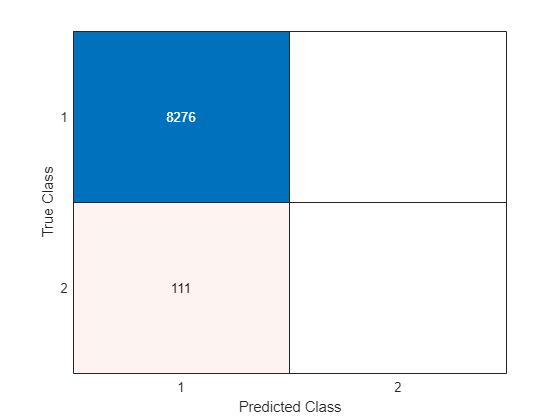

accuracy = 0.9868

precision = NaN

recall = 0

specificity = 1

fb = 0

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'prior', 'empirical', 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

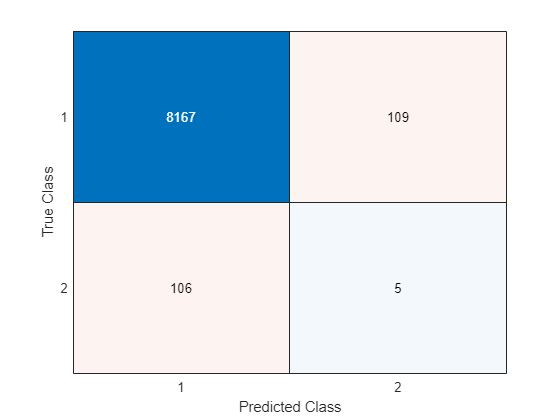

accuracy = 0.9744

precision = 0.0439

recall = 0.0450

specificity = 0.9868

fb = 0.0444

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Prior', 'empirical', 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

% ********** 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy) **********

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1

ParamsDT = [prior, MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
dstWeight = optimizableVariable('dstWeight', {'equal','inverse', 'squaredinverse'},'Type','categorical');  % default: equal

ParamsKNN = [prior; n; dst; dstWeight];

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.22627 |     0.41287 |     0.22627 |     0.22627 |      uniform |           19 |           19 |
|    2 | Accept |     0.22984 |     0.43735 |     0.22627 |     0.22805 |      uniform |           27 |           14 |
|    3 | Best   |    0.015919 |     0.42735 |    0.015919 |    0.015972 |    empirical |           18 |           13 |
|    4 | Best   |     0.01586 |     0.43522 |     0.01586 |    0.015885 |    empirical |           29 |           16 |
|    5 | Accept |    0.015979 |     0.43657 |   

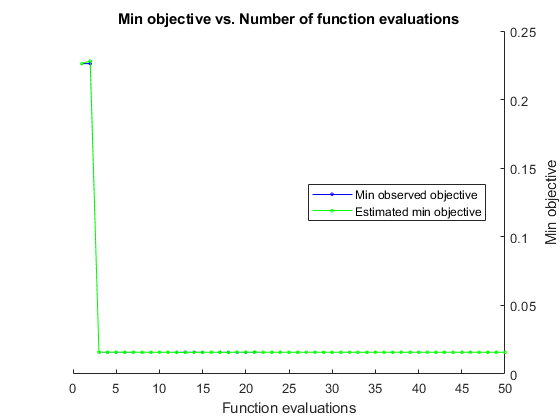


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 29.749 seconds
Total objective function evaluation time: 18.7882

Best observed feasible point:
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical        29             16     

Observed objective function value = 0.01586
Estimated objective function value = 0.015958
Function evaluation time = 0.43522

Best estimated feasible point (according to models):
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical         3             30     

Estimated objective function value = 0.015853
Estimated function evaluation tim

% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'prior', char(params.prior), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9868

precision = NaN

recall = 0

specificity = 1

fb = 0

% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.018215 |      2.0903 |    0.018215 |    0.018215 |    empirical |            4 |    euclidean | squaredinver |
|    2 | Accept |     0.47337 |      1.9936 |    0.018215 |    0.036312 |      uniform |            2 |       cosine |      inverse |
|    3 | Accept |     0.37042 |      2.0961 |    0.018215 |    0.018545 |      uniform |           17 |       cosine | squaredinver |
|    4 | Accept |     0.38458 |      2.0912 |    0.018215 |   

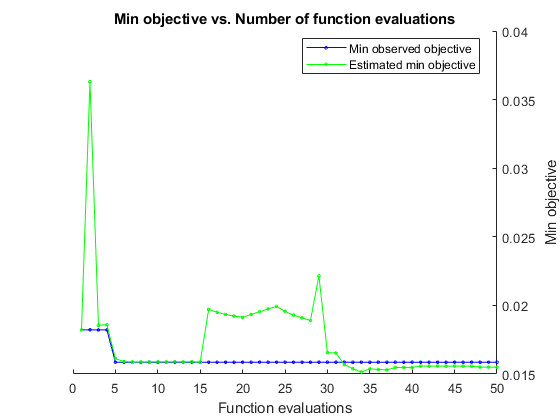


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 114.9355 seconds
Total objective function evaluation time: 104.5644

Best observed feasible point:
      prior      n      dst      dstWeight
    _________    __    ______    _________

    empirical    19    cosine      equal  

Observed objective function value = 0.01586
Estimated objective function value = 0.015649
Function evaluation time = 2.0978

Best estimated feasible point (according to models):
      prior      n        dst         dstWeight   
    _________    __    _________    ______________

    empirical    14    euclidean    squared

% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'CVPartition', c, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

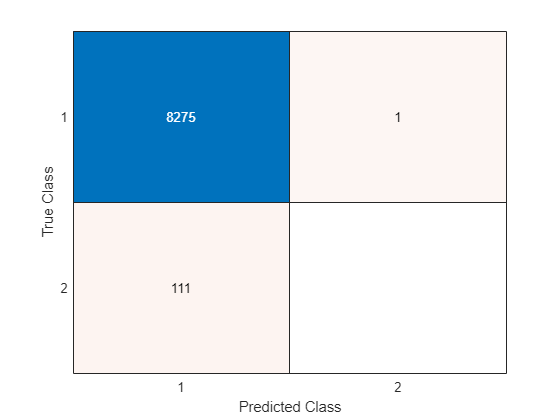

accuracy = 0.9866

precision = 0

recall = 0

specificity = 0.9999

fb = 0

% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta) **********

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.99266 |     0.43681 |     0.99266 |     0.99266 |    empirical |           24 |            5 |
|    2 | Best   |     0.92979 |     0.27265 |     0.92979 |     0.93487 |      uniform |            2 |           17 |
|    3 | Best   |     0.90136 |     0.36745 |     0.90136 |     0.90142 |      uniform |            9 |           25 |
|    4 | Accept |           1 |     0.27446 |     0.90136 |     0.90138 |    empirical |            2 |           11 |
|    5 | Accept |     0.90561 |     0.41243 |   

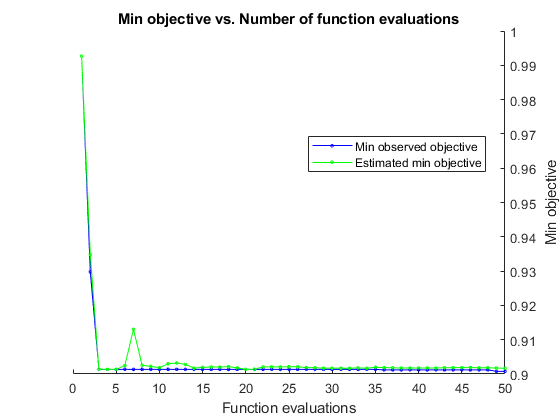


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 30.0996 seconds
Total objective function evaluation time: 19.2181

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform         8              1     

Observed objective function value = 0.90077
Estimated objective function value = 0.90337
Function evaluation time = 0.37736

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        10              1     

Estimated objective function value = 0.90167
Estimated function evaluation time = 0.36772



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

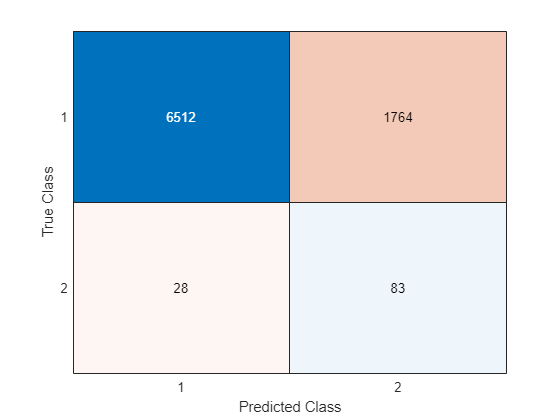

accuracy = 0.7863

precision = 0.0449

recall = 0.7477

specificity = 0.7869

fb = 0.0848


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.91522 |       2.071 |     0.91522 |     0.91522 |      uniform |            6 |    euclidean |      inverse |
|    2 | Accept |     0.93074 |      2.1329 |     0.91522 |     0.91584 |      uniform |           18 |  correlation |      inverse |
|    3 | Accept |     0.99626 |      2.0791 |     0.91522 |     0.94739 |    empirical |           10 |    euclidean |      inverse |
|    4 | Accept |     0.99625 |      2.0873 |     0.91522 |   

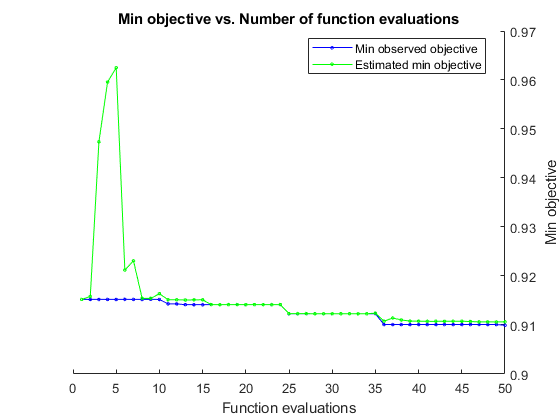


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 114.1359 seconds
Total objective function evaluation time: 103.8988

Best observed feasible point:
     prior     n        dst         dstWeight   
    _______    __    _________    ______________

    uniform    11    euclidean    squaredinverse

Observed objective function value = 0.90995
Estimated objective function value = 0.91009
Function evaluation time = 2.0924

Best estimated feasible point (according to models):
     prior     n        dst       dstWeight
    _______    __    _________    _________

    uniform    11    euclidean     inver

% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

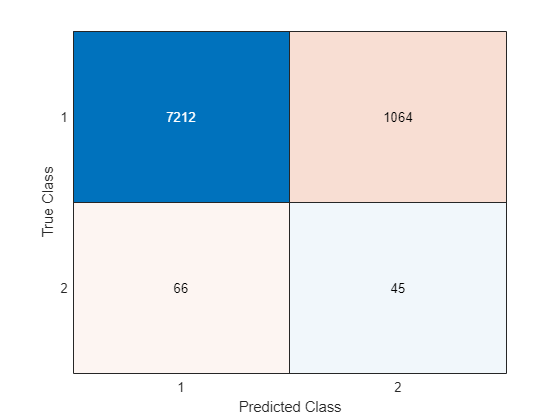

accuracy = 0.8653

precision = 0.0406

recall = 0.4054

specificity = 0.8714

fb = 0.0738


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta) **********

% CV SPLITS (Stratified)
c = cvpartition(y_train,'KFold', 20, 'Stratify', true);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |           1 |     0.40312 |           1 |           1 |    empirical |           15 |            4 |
|    2 | Accept |           1 |     0.37445 |           1 |           1 |    empirical |           11 |           27 |
|    3 | Best   |     0.92917 |     0.27056 |     0.92917 |     0.92917 |      uniform |            2 |            9 |
|    4 | Accept |           1 |     0.21987 |     0.92917 |     0.92917 |    empirical |            1 |           29 |
|    5 | Best   |     0.90595 |     0.41858 |   

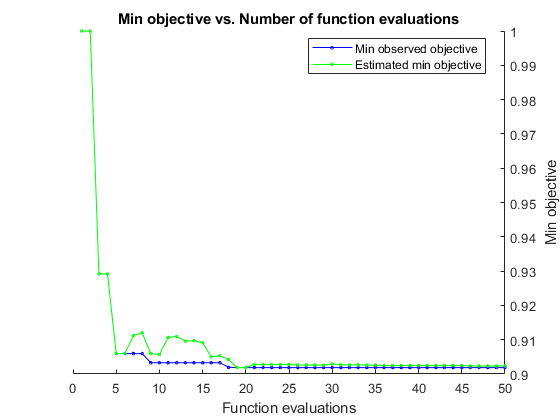


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 30.5543 seconds
Total objective function evaluation time: 19.4221

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform         9             30     

Observed objective function value = 0.90188
Estimated objective function value = 0.90283
Function evaluation time = 0.36404

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        10             30     

Estimated objective function value = 0.90238
Estimated function evaluation time = 0.36839



% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

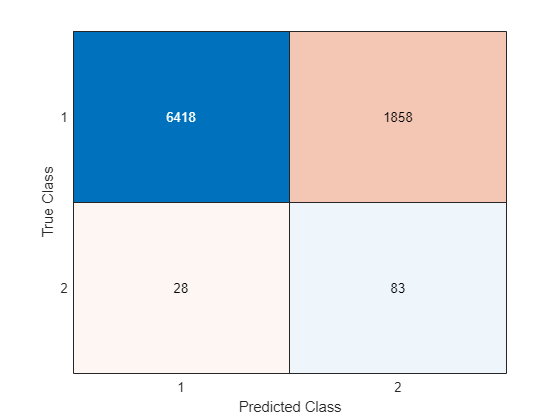

accuracy = 0.7751

precision = 0.0428

recall = 0.7477

specificity = 0.7755

fb = 0.0809


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****')

***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****



% i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c) % see helper function

loss = function_handle with value:
    @(params)fb_loss_knn_cv(params,X_train,y_train,c)


|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |           1 |      2.0594 |           1 |           1 |    empirical |           12 |    euclidean | squaredinver |
|    2 | Best   |     0.93387 |      2.1174 |     0.93387 |      0.9365 |      uniform |           14 |  correlation |      inverse |
|    3 | Accept |           1 |      2.0931 |     0.93387 |     0.93656 |    empirical |           11 |       cosine |        equal |
|    4 | Accept |     0.98537 |      2.0509 |     0.93387 |   

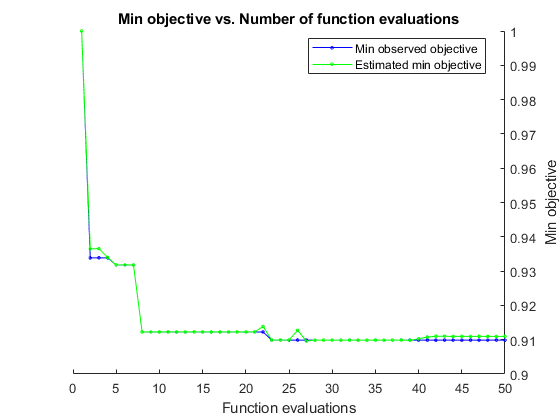


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 114.4395 seconds
Total objective function evaluation time: 104.4872

Best observed feasible point:
     prior     n        dst       dstWeight
    _______    __    _________    _________

    uniform    13    euclidean      equal  

Observed objective function value = 0.90988
Estimated objective function value = 0.91128
Function evaluation time = 2.0933

Best estimated feasible point (according to models):
     prior     n        dst       dstWeight
    _______    __    _________    _________

    uniform    12    euclidean     inverse 

Estimated 


% ii) Optimize model
results = bayesopt(@(params)fb_loss_knn_cv(params,X_train,y_train, c), ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

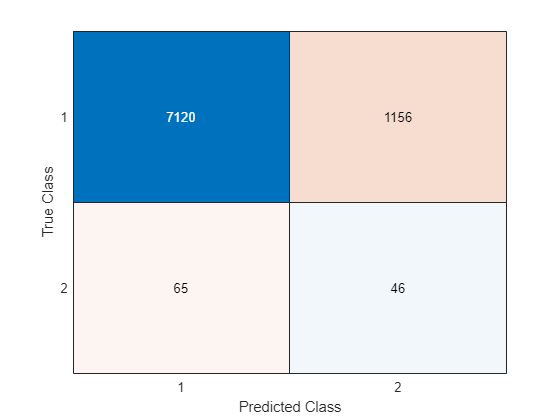

accuracy = 0.8544

precision = 0.0383

recall = 0.4144

specificity = 0.8603

fb = 0.0701


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'prior', char(params.prior), ...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 